# Data Processing Tutorial

## Introduction

This script demonstrates how to processing data from a csv file after running a Spasticity Emulator trial on the KinArm Endpoint robot. If you have yet to collect any data, you can begin [here](https://github.com/Neuromechanics-Lab/Spasticity-Emulator/blob/main/README.md), and then return to this script. 

In this script, we load the forces at the hand, as well as the model parameters to calculate the torque of the limb. We also load the position and velocity data of the handle and use a [Hill-type model](https://en.wikipedia.org/wiki/Hill%27s_muscle_model) to calculate the theoretical force produced by the muscle given its length and velocity. From this muscle force, we can calculate the theoretical torque at the handle. Our desired outcome is that the first measured torque is similar to the theoretical torque, as that would confirm that the robot produces the forces we want it to. 

## Loading the File

Let's start by opening the file of the trial we want to analyze. In the current workspace, there is a sample trial file called "SRS_9.csv." You can load your own trial or use the same one.

filename= "/MATLAB Drive/spasticity_demo/SRS_9.csv"

filename = "/MATLAB Drive/spasticity_demo/SRS_9.csv"

Once you have selected a file, use the readmatrix function to load the timeseries data. The first 250 or so rows contain information about the trial from the Trial Protocol. This information is pivotal for accurate data processing, but is harder to read from the file due to its structure. I reccomend you open the csv file in excel and hard code the parameters into your processing script, as we will do later. 

In excel, find the row where the value under column "Frame #" is 0. This is the first frame of the trial and where we want to begin loading the data from. For the sample file, this is row 273. However, if you use a different model or trial protocol, the different number of variables may result in the trial starting at a different row. Make sure to open the file in excel to see for yourself. 

trial = readmatrix(filename, 'Range', 273);

The excel file also gives us column headers for the timeseries data, which I have put here. Assign any important column numbers to variables so that you can easily access the individual signals from the larger trial matrix. For example, to get all of the Frame numbers (our measure of time) we would write the following: 

Frame = 10; %We use the frame number to track time. 1000 frames are recorded per second

%Force Sensors in the handle output the X and Y components of Force
%measured as individual signals
FS_X = 20; FS_Y = 21;

%ACH = Analog Channel. These are added in the build file and are not
%default kinarm outputs. These can be added or removed from the Simulink
%model, and you can choose to save or not save them in the trial protocol
%within Dexterit-E.
len_ACH = 49; % muscle length
vel_ach = 50; % muscle velocity
activation = 51; %muscle activation
torque_analog = 52; %simulink-commanded torque
SRS_gain = 53; %signal measuring the Short Range Stiffness contribution to stiffness

%Cartesian coordinates of the handle, and velocity of the handle in 2D
%space
Hand_PositionX = 54; Hand_PositionY = 55; speed = 56; vel_x = 57; vel_y = 58;
%Acceleration of the handle
acc = 59; acc_X = 60; acc_Y = 61; 
% 'Commanded' Force at the Handle: The force that the KinArm computer
% commands the robot to produce given the simulation state. 
Cmd_X = 62; Cmd_Y = 63; Cmd = 64;

Our current goal is to reproduce the measured handle forces using only the file's data on the position and velocity of the handle, so that we can confirm that the force we measured is what we would expect given the input parameters (position and velocity). 

Consequently, we are going to calculate the length and velocity of the muscle at each time point in the trial and put the values into our hill model. This is exactly what the simulink model does when it produces the forces, but we want to do the calculations independently so confirm that the robot is accurate. 

## Hill Model

Let's load the Hill Model now, and visualize the Force-Length and Force-Velocity curves to make sure we processed it correctly. 

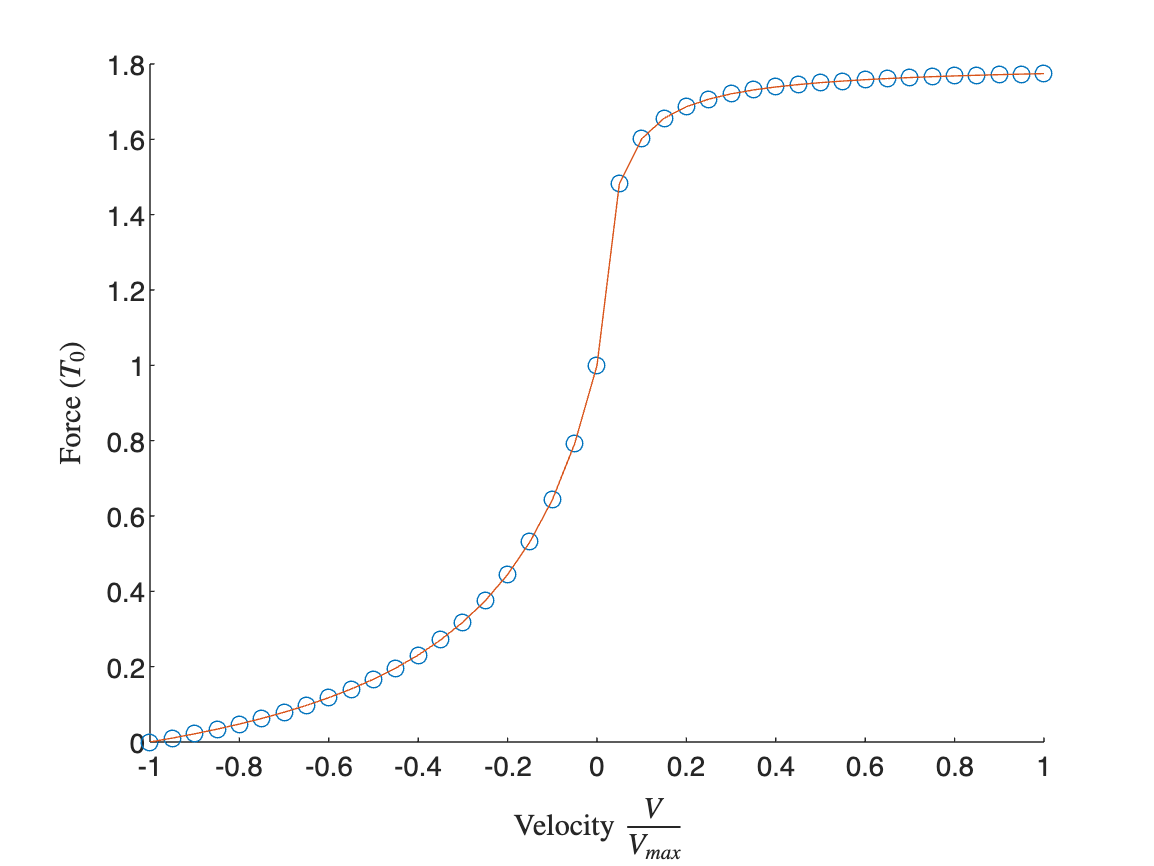


% Load the Hill Model Data, and interpolate the curves to create continuous functions for smooth lookup
load("force_curves.mat");
%  Force Velocity Curve
f = fvCurve(:,2); 
v = fvCurve(:,1);

fv_int = spline(v, f);

figure(1)
scatter(v,f)
xlabel("Velocity $\frac{V}{V_{max}}$", 'interpreter', 'latex')
ylabel("Force ($T_0$)", 'interpreter', 'latex')
hold on
xx = -1:0.05:1;
plot(xx, ppval(xx,fv_int));

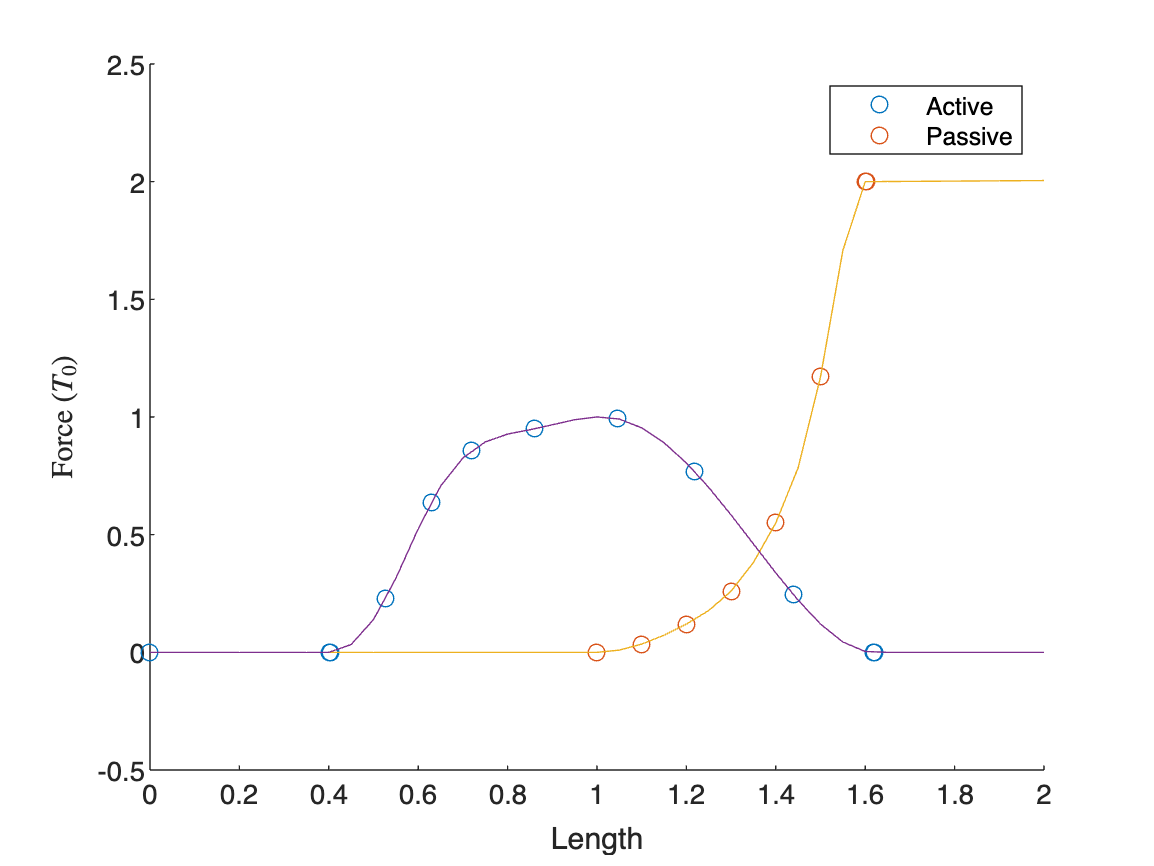

%%
% Force Length Active and Passive
fa = flaCurve(:,2);
la = flaCurve(:,1);
fa_int = spline(la, fa);

fp = flpCurve(:,2);
lp = flpCurve(:,1);
fp_norm = fp ./max(fp); %normalize y values

fp_int = spline(lp, fp);

f_tot = ppval(fp_int, lp) + ppval(fa_int, lp);
ft_int = spline(lp, f_tot);

figure(2)
scatter(la, fa)
xlabel("Length")
ylabel("Force ($T_0$)", 'interpreter', 'latex')
hold on
scatter(lp, fp)

xlim([0, 2.0])
%%
xx = 0:0.05:2.0;
plot(xx, ppval(xx, fp_int))
hold on
plot(xx, ppval(xx, fa_int))
hold off
legend(["Active", "Passive"])

## Inverse Kinematics

Now, let's define the parameter values so we can get our important measurements. 

We want to get the muscle length, the derivative of that length (velocity), and the torque felt at the hand. To get these we need proper measurements of each segment of the limb and the muscle insertion point, from which we can derive the angles between the muscle force and the forearm. Then we can finally calculate the torque. 

As mentioned previously, you can get the parameter values from the csv file. Here I have hard coded the parameter values for the "SRS_9.csv" trial. Change, add, or remove parameters as you see fit. 

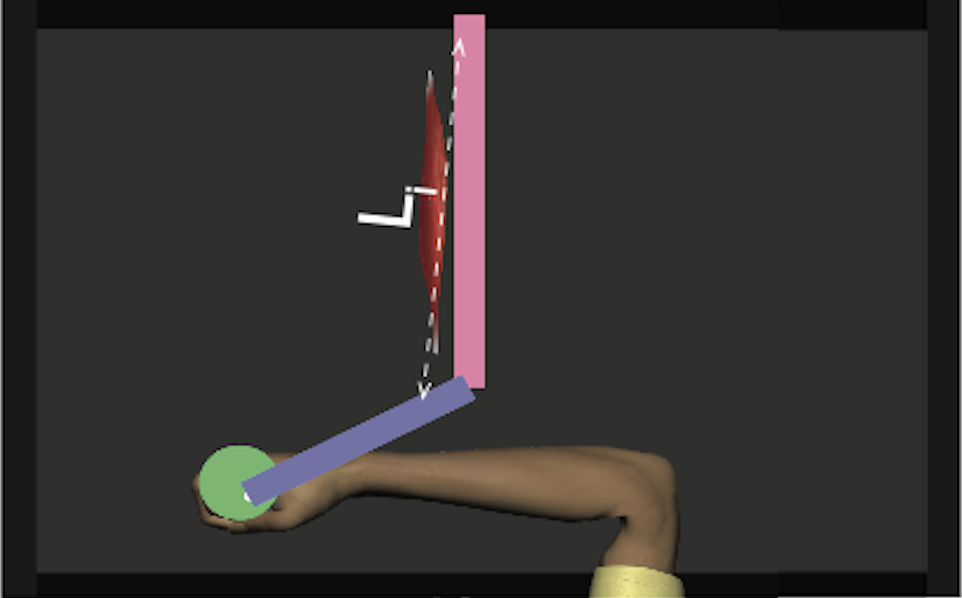

The values used here have been selected based on resemblance of appropriate ratios between limb lengths, as well as accomodating the spatial limitations of the KinArm. 

l0 = 0.291;

$L_0 \;$equals the resting length of the muscle. 

t_0 = 15.0; %resting tension in newtons

$T_0$ equals the baseline isometric tension of the muscle at rest. This is the value we use to standardize our hill model forces, but here it is translated into Newtons, since those are the units of the KinArm force measurements.

Vmax = 5; % units of Vmax are 5 resting lengths per second

$V_{max}$ gives the maximum velocity, measured in $\frac{L_0}{s}$ of a muscle. This is defined empirically by finding the shortening velocity at which zero force is produced. This can be seen on the FV curve at the minimum X value. 

Here we arbitrarily set the value to 5. It is usually between 5 and 15 resting lengths per second for a muscle. 


origin = [0,0.52]; % These are the cartesian coordinates of the origin of the upper arm (L1) shank.
% i.e, the top of the simulated shoulder
% this is defined under 'Task Wide Parameters' in Dexterit-E. 

d = 0.08; %insertion point of muscle in forearm, measured as proportion of forearm total length

L1 = 0.29; L2 = 0.2; %L1 = length of upper arm % L2 = length of forearm (rotating shank)

elbow_pos= [0, (origin(2) - L1)]; % cartesian position of joint based on limb definitions

L1_vec = origin - elbow_pos; %vector of upper arm from origin to elbow 

muscle_act = trial(:,activation); %activation level of the muscle, stored as analog channel

hand_pos = [trial(:,Hand_PositionX) trial(:,Hand_PositionY)]; %position of the hand in 2D space

hand_force = [trial(:, Cmd_X) trial(:, Cmd_Y)]; %force commanded by KinArm at the hand

hand_FS = [trial(:,FS_X), trial(:,FS_Y)]; % force measured by force sensors at the hand
L2_vec = hand_pos - elbow_pos; %vector from joint to hand
    
insertion_offset = (d/L2) * L2_vec; % length of insertion point along forearm
    
insertion_vec = insertion_offset - elbow_pos; %vector from elbow to insertion point
insertion_pos = elbow_pos + insertion_offset; %coordinate position of muscle insertion

muscle_vec = origin - insertion_pos; % vector of muscle from origin to insertion point 

muscle_len = zeros(length(insertion_vec), 1); %length of the muscle

theta = zeros(length(insertion_vec), 1); % empty n*1 vectors for later
beta = zeros(length(insertion_vec), 1);

thetatorqued = zeros(length(insertion_vec),1); 
costheta = zeros(length(insertion_vec),1);
thetatorque = zeros(length(insertion_vec), 1);

thetatorqued2 = zeros(length(insertion_vec),1);

joint_ang = zeros(length(insertion_vec), 1);
orth_ang = zeros(length(insertion_vec), 1);


Now that we've defined the empty vectors that we will need, as well as defined the parameter values, let's run a loop to calculate other variables at each point in time. Specifically, let's use the vectors of the forearm and the muscle to calculate the joint angle, and the torque at the hand. 


for i = 1:length(insertion_vec)
    theta(i) = subspace(L2_vec(i,:)', insertion_vec(i,:)'); % angle b/w forearm and muscle
    muscle_len(i) = sqrt(sum(muscle_vec(i,:).^2)); %instantaneous muscle length
    beta(i) = subspace(L2_vec(i,:)', hand_force(i,:)'); %angle b/w force at the hand and the forearm
    %this angle helps us do inverse kinematics to calculate the torque at the hand!
    
    % %x1 and y1 form a vector of a horizontal line (such as the x axis)
    %x2 and y2 are the components of the L2 vector for ease of calculation
    x1 = 1; y1 = 0; x2 = L2_vec(i,1); y2 = L2_vec(i,2);


[**atan2**](https://www.mathworks.com/help/matlab/ref/atan2.html) (Y,X) gives us the angle between the two vectors, here we are measuring the angle between the horizontal and the forearm. The horizontal is just used as a standard in this case, since a normal quadrant system measures <1,0> vector as being 0 degrees.

    joint_ang(i) = atan2(x1*y2 - y1*x2, x1*x2 + y1*y2); 

We can then rotate that angle by pi/2 to get the angle perpindicular to the forearm. 

    orth_ang(i) = joint_ang(i) - (pi/2); 
    %%
    % Calculate the norm of the cross product between the muscle and the forearm
    % vectors, and the dot product between the muscle and forearm and take the arctangent.
    %% 
    
    u = [muscle_vec(i,:), 0];
    v1 = [L2_vec(i,:), 0];
        
    thetatorqued(i) = atan2d(norm(cross(u,v1)), dot(u,v1));    
    costheta(i) = max(min(dot(u,v1)/norm(u)*norm(v1),1),-1); 
    thetatorque(i) = real(acos(costheta(i)));

end

We can get the angle between two vectors using inverse trigonometry. Since the sine and cosine functions can be defined using vector norm, cross product, and dot product, we can derive a similar formula for the tangent. 

We can then use the arctangent to get the angle between the vectors


$$\cos\theta=\frac{v\cdot w}{\left\|v\right\|\left\|w\right\|}\;,\;\;\sin\theta=\frac{\left\|v\times w\right\|}{\left\|v\right\|\left\|w\right\|}\rightarrow \tan\theta=\frac{\left\|v\times w\right\|}{v\cdot w}$$
 
$$\therefore \theta = \tan^{-1}(\frac{\left\|v\times w\right\|}{v\cdot w})$$


%%
% Using the Forces at the hand and the angles between the joints and the
% muscle, calculate the torque produced by the muscle

Transform the angle perpindicular to the forearm into a vector. 

orth_v = [cos(orth_ang) sin(orth_ang)];

joint_angd = rad2deg(joint_ang);
orth_angd = rad2deg(orth_ang);
thetad = rad2deg(theta);
betad = rad2deg(beta);

velocity = [trial(:, vel_x), trial(:, vel_y)]; %x and y velocities

hand_speed = trial(:,speed);

Fs = 1000; % Frame rate is 1000 frames per second
speed_raw = [0;diff(muscle_len)*Fs];
N3 = 2; %Order
lb = 10/(0.5*Fs); % Lower cutoff frquency
[b2,a2] = butter(N3,lb,'low');

speed_filt = filtfilt(b2, a2, speed_raw); %filter the speed data 

vel_norm = speed_filt / l0; %resting lengths per second


Vmax_m = Vmax * l0; %convert to m/s
speed_muscle = vel_norm/Vmax; %convert to V/Vmax


len_r = muscle_len./l0;


Our timeseries data has 17000 frames. When running a loop over this data, we don't want to resize arrays each time. For any new timeseries variable, create an empty zeros vector before running a loop so that the computer doesn't waste resources creating a new array with one extra element every iteration of the loop!


pred_force = zeros(length(trial), 1);FV = zeros(length(trial), 1);

mag = zeros(length(trial),1); muscle_force_vec = zeros(length(trial),2);
FLA = zeros(length(trial), 1);FLP = zeros(length(trial), 1); Flen = zeros(length(trial), 1);
normC = zeros(length(trial), 1); normFS = zeros(length(trial), 1); C = zeros(length(trial), 2); C2 = zeros(length(trial),2);
fsintheta = zeros(length(trial),1);

FS = sqrt(trial(:, FS_X).^2 + trial(:, FS_Y).^2);
F = sqrt(trial(:, Cmd_X).^2 + trial(:, Cmd_Y).^2);

reflex_gain = 2.5;
reflex_component = zeros(length(trial),1);

%% Calculate orthogonal force at hand

Since we are dealing with rotational motion, we measure the torque of the system, which is defined as follows:  $$$ \tau = r \cdot F \cdot \sin(\theta)$$$.

The force is produced by the muscle in the direction of the origin (since the muscle produces by contracting). Only the component of this force that is perpindicular to the forearm creates any force, because the joint is fixed about the elbow and thus the forearm cannot move laterally. 

Given the force at the hand, we calculate  $F \cdot \sin(\theta)$ as the vector component of the force that is perpindicular to the forearm, since that is where $\theta = 90 \degree \therefore \sin(90\degree) = 1$ 

To get that vector component, we use the vector projection formula $proj_v{a} = \frac{a \cdot v} {||v||^2} \cdot v$

Here, we do that calculation for the force sensor variable hand_FS, as well as the hand_force variable that measures commanded force. We store the results in C2 and C variables respectively. 

for i = 1:length(trial)
    FV(i) = ppval(fv_int, speed_muscle(i));
    FLA(i) = max(0, ppval(fa_int, len_r(i)));
    FLP(i) = ppval(fp_int, len_r(i));
    %Flen(i) = FLA(i) + FLP(i);
    pred_force(i) = ((FV(i) * FLA(i)) + FLP(i)) * t_0;
    mag(i) = norm(muscle_vec(i,:));

    muscle_force_vec(i,:) = (pred_force(i) / mag(i)) * muscle_vec(i,:);
   


    A = hand_force(i,:); %CMD hand forces
    A2 = hand_FS(i,:);
    A3 = muscle_force_vec(i,:);

    B = orth_v(i,:); %vector orthogonal to the forearm, at the timepoint i 
    
    
    C(i,:) = (dot(A,B)/norm(B)^2)*B; % commanded force perpindicular to arm
    C2(i,:) = (dot(A2,B)/norm(B)^2) *B; % force sensor component perpindicular to arm

    normC(i) = norm(C(i,:));     

    normFS(i) = norm(C2(i,:));
    fsintheta(i) = norm((dot(A3,B)/norm(B)^2) * B); %magnitude of perpindicular force produced by hill model
    
end

For the torque produced by the muscle, the radius is the distance between the muscle insertion and the joint.

For the torque felt at the hand, the radius is the length of the forearm (L2). 

Since we already have F sin theta in the form of the vector component, we can just multiply the force by the radius to get the torque. 

% Filter the signal
N3 = 4; 
lb = 5/(0.5*Fs); % Lower cutoff frquency
[b2,a2] = butter(N3,lb,'low');


torq_cmd = L2 .* normC; % torque produced by the muscle


torq_FS = L2 .* normFS; %convert force sensor to a torque

torque_hill = d .* fsintheta;

torq_hill = d .* pred_force .* sind(thetatorqued);

SRS = trial(:,SRS_gain); %force from SRS

SRS_f = SRS .* sind(thetatorqued);

SRS_torque = L2 .* SRS .* sind(thetatorqued); 

torque_sum = L2 .* (SRS_f + fsintheta)

torque_sum =     2.5821
    2.5818
    2.5814
    2.5811
    2.5808
    2.5806
    2.5803
    2.5800
    2.5797
    2.5794


## Calculate Error

To measure the error of our simulation, let's compare the predicted forces versus the measured forces. To do this we will fit a linear model of the two datasets, and then calculate the MSE between them. 

residuals = torq_FS - torq_cmd; 
mdl = fitlm(torq_cmd, torq_FS);
mdl_pred = fitlm(torq_hill + SRS_torque, torq_cmd);
mse_pred = mdl_pred.MSE;
mse_val = mdl.MSE;

## Generate Plots

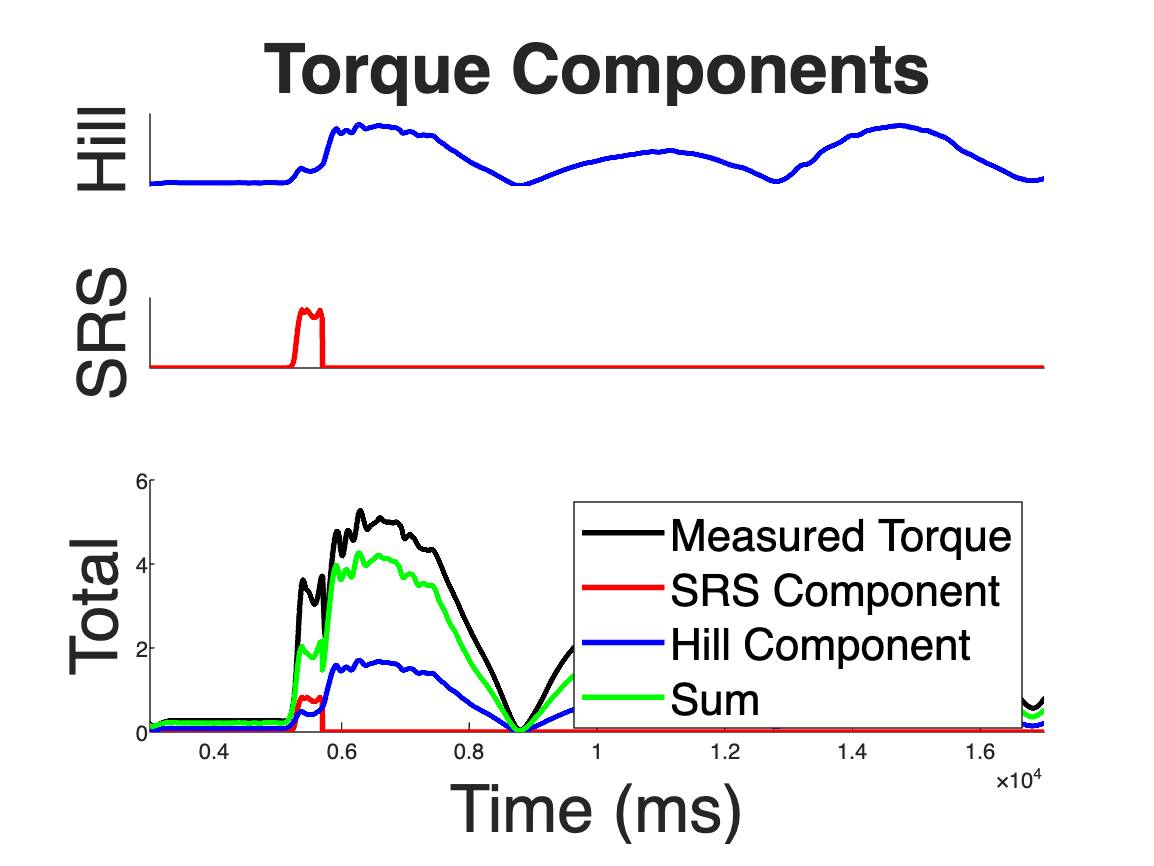


range = [3000, 17000]; %Crop irrelevant frames from the trial
figure(3);
maxtiles = 5;
t = tiledlayout('flow');
nexttile([1, maxtiles]) %FIRST ONE
plot(trial(:, Frame), torq_hill,'LineWidth', 2.0,'color', 'b')
ax1 = gca(); 
ax1.XAxis.FontSize = 16;
ax1.YAxis.FontSize = 16;

hFig = gcf;
color = get(hFig, 'Color');
set(ax1,'XColor', 'none', 'TickDir', 'out');
ylabel("Hill", 'FontSize', 24)
%legend(["Commanded Torque","Measured Torque"], 'fontsize', 24);
set(ax1, 'TickDir', 'out')

xlim(range)
yticks([])
box off

nexttile([1, maxtiles])

plot(trial(:,Frame), SRS_torque, 'LineWidth', 2, 'color', 'r')
xlim(range)
ax3 = gca(); 
ax3.XAxis.FontSize = 16;
ax3.YAxis.FontSize = 16;
set(ax3, 'TickDir', 'out')
ylabel("SRS", 'FontSize', 24)
yticks([])
xticks([])
box off

% plot(trial(:,Frame), SRS_torque, 'LineWidth', 2, 'color', [0.5 1 0.1])

nexttile([2, maxtiles])
plot(trial(:,Frame), torq_cmd, 'LineWidth', 2, 'color', 'k');
% hold on
% plot(trial(:,Frame), torq_FS, 'LineWidth', 2, 'color', [0.2, 0.0, 0 0.8]);
ax = gca(3); 
ax.XAxis.FontSize = 16;
ax.YAxis.FontSize = 16;
ylabel("Total", 'FontSize', 24)
xlabel("Time (ms)",'FontSize', 24)
xlim(range)
hold on 
plot(trial(:,Frame), SRS_torque, 'color', 'r', 'LineWidth', 2)
hold on 
plot(trial(:,Frame), torque_hill, 'color', 'b', 'LineWidth', 2)
hold on 
plot(trial(:,Frame), torque_sum, 'color', 'g', 'LineWidth', 2)
hold off
box off


l = legend(["Measured Torque", "SRS Component", "Hill Component", "Sum"]);
l.FontSize = 16;
title(t, "Torque Components", 'FontSize', 25, 'FontWeight', 'bold')